# Modelagem dinâmica a partir de dados reais

## Boas práticas

clear all;          %%% Limpa as variáveis
close all;          %%% fecha as figuras
clc;                %%% limpa a tela

%%% https://www.youtube.com/watch?v=Q832jvYdnzY

## Lendo os dados reais a partir d eum arquivo .txt

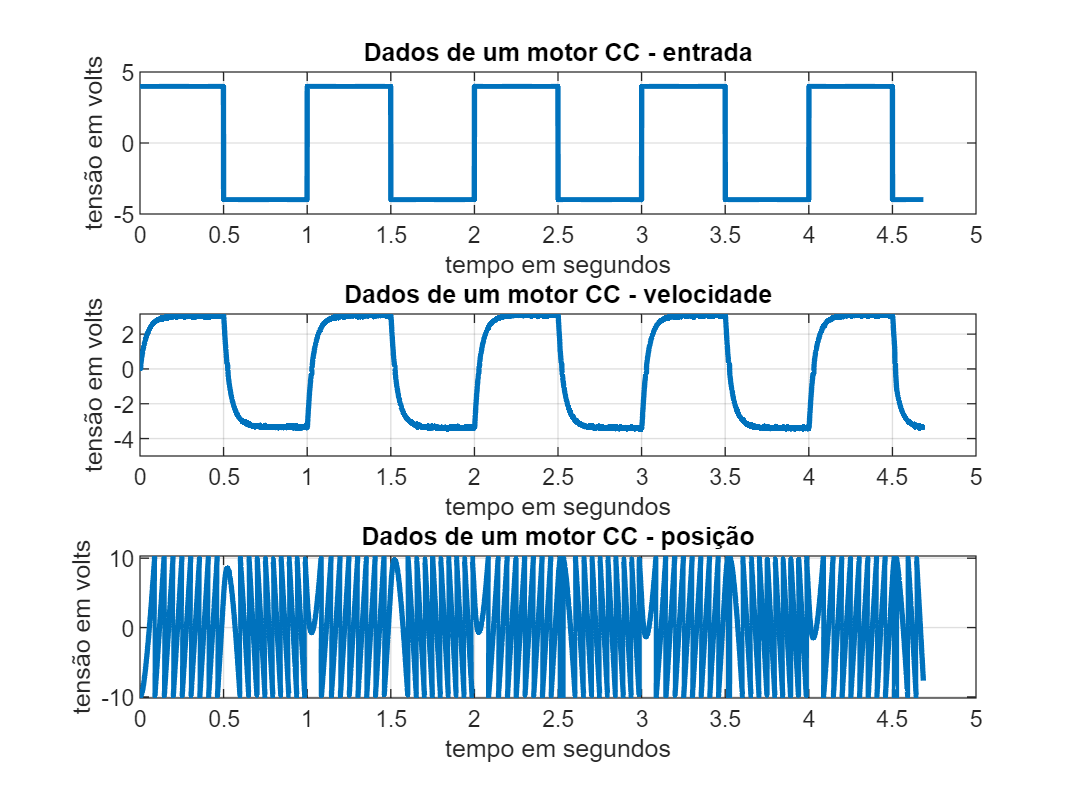

%%% Ler o arquivo de dados

LeitorDados;

%%% Visualizando os dados
%%% Informações do sistema de aquisição

T = 1e-3;                   %%% taxa de amostragem
N = length(Entrada);        %%% Número de pontos

%%% criando o vetor tempo

tempo = linspace(0,N*T,N);

%%% Visualizando os dados

figure(1)

subplot(3,1,1)  %%% primeiro gráfico em 3 linhas e 1 coluna

plot(tempo,Entrada,'LineWidth',2)
title('Dados de um motor CC - entrada')
xlabel('tempo em segundos')
ylabel('tensão em volts')
grid

subplot(3,1,2)  %%% segundo gráfico em 3 linhas e 1 coluna

plot(tempo,Velocidade,'LineWidth',2)
title('Dados de um motor CC - velocidade')
xlabel('tempo em segundos')
ylabel('tensão em volts')
grid

subplot(3,1,3)  %%% terceiro gráfico em 3 linhas e 1 coluna

plot(tempo,Posicao,'LineWidth',2)
title('Dados de um motor CC - posição')
xlabel('tempo em segundos')
ylabel('tensão em volts')
grid

## Estimando um modelo em Laplace para os dados

O sinal de entrada $U(s)$ foi aplicado a um sistema cuja função de transferência gerou o sinal $\Omega(s)$. Logo a relação entre entrada e saída é dada pela função de transferência:

$\frac{\Omega(s)}{U(s)} =  \frac{K_m}{s+p_m}$ . Neste caso supomos ser de primera ordem pelo aspecto geral do sinal **Rotação**.

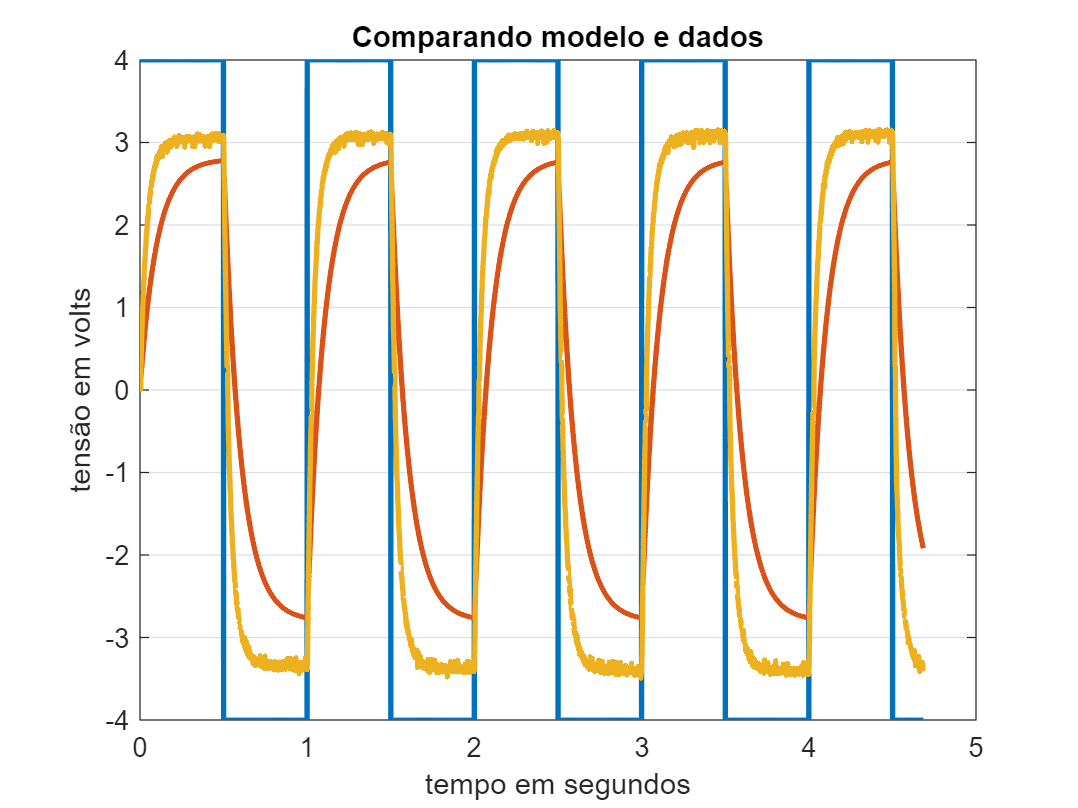

%%% Valores iniciais de Km e pm

Km  = 7;             %%% ganho inicial
pm  = 10;            %%% polo inicial

%%% Criando a função de transferência do modelo

Gp = tf(Km,[1 pm]);

%%% Simular o modelo com a mesma entrada

ym = lsim(Gp,Entrada,tempo);

figure(2)

% subplot(3,1,1)  %%% primeiro gráfico em 3 linhas e 1 coluna

plot(tempo,Entrada,tempo,ym,tempo,Velocidade,'LineWidth',2)
title('Comparando modelo e dados')
xlabel('tempo em segundos')
ylabel('tensão em volts')
grid

## Sintonizando os valores do modelo a partir dos dados

x0 = [1 1];                 % condição inicial Km = 1 e pm = 1

X = fminsearch(@(x) ErroQuadratico(x,Velocidade,tempo,Entrada) ,x0) 

X =    22.4732   28.0882


## Comparando o modelo com os dados

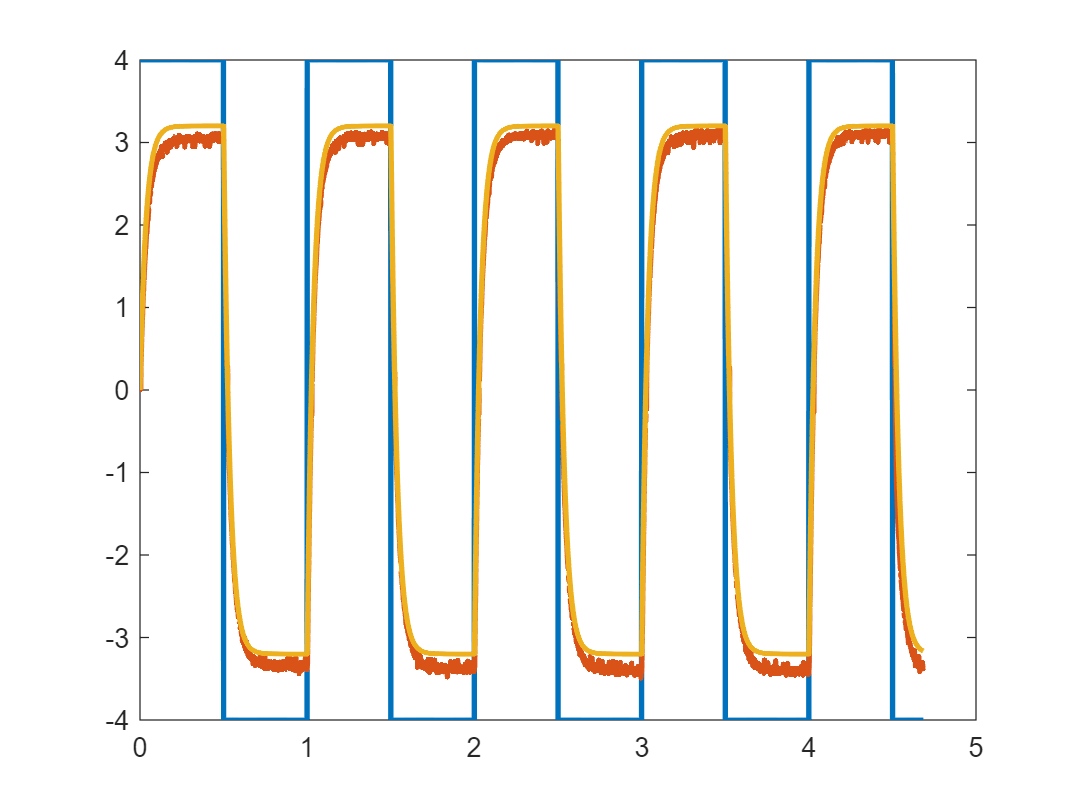

%%% Atualizando os valores

Km  = X(1);
pm  = X(2);

%%% Montagem da função de transferência

Gp  = tf(Km, [1 pm]);

 %%% Aplico no modelo  a mesma entrada que apliquei no sistema real

 ym   = lsim(Gp,Entrada,tempo); 

 %%% Visualizando o resultado

 figure(3)

 plot(tempo,Entrada,tempo,Velocidade,tempo,ym,'LineWidth',2)